% Fetch and extract dataset - Note the repo referenced below is public and
% contains this dataset and a single text file needed to cut the release
% hosting this dataset - Feel free to explore or disregard as your pleasure

fetchDataset("https://github.com/johnwparent/machine-learning-anxiety-biosignals/releases/latest/download/Data.zip")

% Load data into memory and compute selected features
% After performing statistical test
feature_array = compose_data_to_feature_space();

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [6.3501 6.3501 6.3501 6.3501 6.3501 6.3504 6.3510 6.3514 6.3523 6.3530 6.3539 6.3552 6.3562 6.3575 6.3587 6.3600 6.3616 6.3629 6.3645 6.3661 6.3674 6.3690 6.3706 6.3722 6.3738 6.3754 6.3770 6.3783 6.3799 6.3815 … ]
             smoothedRespiration: [5.9982 6.0295 6.0594 6.0880 6.1152 6.1411 6.1656 6.1888 6.2107 6.2312 6.2503 6.2681 6.2846 6.2996 6.3134 6.3257 6.3367 6.3463 6.3545 6.3614 6.3669 6.3709 6.3736 6.3749 6.3762 6.3775 6.3787 6.3800 6.3813 6.3825 … ]
    baselineCorrectedRespiration: [0.2725 0.3038 0.3337 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 5.9999
Average Peak Inspiratory Flow : 0.70311
Average Peak Expiratory Flow : -0.27589
Average Inhale Volume : 641.02
Average Exhale Volume : 737.42
Average Tidal Volume : 1378.4
Minute Ventilation : 229.74
Duty Cycle of Inhale : 0.24633
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.75167
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.00073816
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.030698
Coefficient of Variation of Exhale Pause Duty Cycle

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [5.4711 5.4708 5.4708 5.4704 5.4701 5.4698 5.4695 5.4692 5.4688 5.4685 5.4685 5.4682 5.4679 5.4676 5.4672 5.4672 5.4669 5.4666 5.4663 5.4660 5.4660 5.4656 5.4653 5.4653 5.4650 5.4650 5.4647 5.4647 5.4644 5.4644 … ]
             smoothedRespiration: [4.9182 4.9661 5.0118 5.0553 5.0966 5.1357 5.1726 5.2073 5.2398 5.2701 5.2982 5.3242 5.3479 5.3695 5.3888 5.4060 5.4210 5.4339 5.4445 5.4530 5.4593 5.4634 5.4654 5.4652 5.4650 5.4648 5.4646 5.4645 5.4643 5.4641 … ]
    baselineCorrectedRespiration: [-0.4801 -0.4322 -0.38

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.23313
Average Peak Expiratory Flow : -1.3081
Average Inhale Volume : 248.8
Average Exhale Volume : 524.46
Average Tidal Volume : 773.26
Minute Ventilation : 128.88
Duty Cycle of Inhale : 0.42424
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.57499
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.0039556
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.00020352
Coefficient of Variation of Exhale Pause Duty Cycle : NaN

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [5.7901 5.7923 5.7949 5.7971 5.7993 5.8016 5.8038 5.8061 5.8083 5.8102 5.8122 5.8141 5.8160 5.8176 5.8192 5.8211 5.8227 5.8244 5.8256 5.8272 5.8288 5.8304 5.8317 5.8333 5.8349 5.8365 5.8381 5.8397 5.8413 5.8433 … ]
             smoothedRespiration: [5.6722 5.6846 5.6966 5.7081 5.7191 5.7297 5.7398 5.7495 5.7586 5.7673 5.7755 5.7832 5.7904 5.7972 5.8035 5.8092 5.8145 5.8193 5.8236 5.8275 5.8308 5.8337 5.8360 5.8379 5.8398 5.8417 5.8436 5.8455 5.8474 5.8494 … ]
    baselineCorrectedRespiration: [-0.1635 -0.1511 -0.13

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33336
Average Inter-Breath Interval : 2.9997
Average Peak Inspiratory Flow : 0.31491
Average Peak Expiratory Flow : -0.34222
Average Inhale Volume : 295.21
Average Exhale Volume : 295.1
Average Tidal Volume : 590.31
Minute Ventilation : 196.79
Duty Cycle of Inhale : 0.53872
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.46008
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.13997
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.042066
Coefficient of Variation of Exhale Pause Duty Cycle : N

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [3.7990 3.7990 3.7990 3.7990 3.7993 3.7993 3.7993 3.7996 3.8000 3.8003 3.8006 3.8012 3.8022 3.8028 3.8038 3.8051 3.8064 3.8080 3.8096 3.8115 3.8137 3.8160 3.8185 3.8208 3.8227 3.8250 3.8266 3.8282 3.8294 3.8307 … ]
             smoothedRespiration: [3.8208 3.8195 3.8183 3.8173 3.8164 3.8156 3.8149 3.8143 3.8139 3.8136 3.8135 3.8134 3.8135 3.8138 3.8142 3.8147 3.8154 3.8162 3.8172 3.8183 3.8196 3.8210 3.8226 3.8244 3.8263 3.8282 3.8303 3.8324 3.8346 3.8369 … ]
    baselineCorrectedRespiration: [-0.4627 -0.4640 -0.46

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 1.6067
Average Peak Expiratory Flow : -0.52721
Average Inhale Volume : 1811.1
Average Exhale Volume : 1811.3
Average Tidal Volume : 3622.3
Minute Ventilation : 603.72
Duty Cycle of Inhale : 0.28967
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.70966
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.00021023
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 7.1834e-05
Coefficient of Variation of Exhale Pause Duty Cycle : N

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [3.8500 3.8503 3.8509 3.8512 3.8519 3.8522 3.8528 3.8532 3.8535 3.8535 3.8535 3.8535 3.8532 3.8528 3.8525 3.8522 3.8519 3.8512 3.8509 3.8503 3.8496 3.8493 3.8484 3.8477 3.8468 3.8458 3.8448 3.8439 3.8429 3.8423 … ]
             smoothedRespiration: [3.8682 3.8668 3.8654 3.8640 3.8627 3.8615 3.8602 3.8590 3.8579 3.8568 3.8557 3.8546 3.8536 3.8527 3.8518 3.8509 3.8501 3.8493 3.8485 3.8478 3.8472 3.8465 3.8460 3.8454 3.8449 3.8443 3.8437 3.8431 3.8424 3.8418 … ]
    baselineCorrectedRespiration: [0.0168 0.0153 0.0139 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.50038
Average Inter-Breath Interval : 1.9985
Average Peak Inspiratory Flow : 0.030819
Average Peak Expiratory Flow : -0.028043
Average Inhale Volume : 12.761
Average Exhale Volume : 20.432
Average Tidal Volume : 33.194
Minute Ventilation : 16.61
Duty Cycle of Inhale : 0.4043
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.59353
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.57123
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.62887
Coefficient of Variation of Exhale Pause Duty Cycle : N

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [5.5663 5.5666 5.5669 5.5673 5.5679 5.5682 5.5689 5.5692 5.5695 5.5698 5.5698 5.5701 5.5701 5.5701 5.5698 5.5698 5.5698 5.5698 5.5698 5.5698 5.5698 5.5695 5.5695 5.5695 5.5695 5.5692 5.5689 5.5689 5.5685 5.5682 … ]
             smoothedRespiration: [5.1710 5.2056 5.2386 5.2701 5.3000 5.3284 5.3552 5.3803 5.4040 5.4260 5.4464 5.4653 5.4826 5.4982 5.5123 5.5249 5.5358 5.5451 5.5529 5.5591 5.5636 5.5666 5.5680 5.5679 5.5677 5.5674 5.5672 5.5669 5.5666 5.5663 … ]
    baselineCorrectedRespiration: [0.2576 0.2923 0.3253 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.49994
Average Inter-Breath Interval : 2.0002
Average Peak Inspiratory Flow : 0.72814
Average Peak Expiratory Flow : -0.50665
Average Inhale Volume : 387.78
Average Exhale Volume : 387.32
Average Tidal Volume : 775.1
Minute Ventilation : 387.5
Duty Cycle of Inhale : 0.48377
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.51388
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.20382
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.56746
Coefficient of Variation of Exhale Pause Duty Cycle : NaN

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [3.6387 3.6387 3.6387 3.6374 3.6345 3.6301 3.6230 3.6131 3.6006 3.5849 3.5663 3.5457 3.5233 3.4999 3.4765 3.4528 3.4300 3.4076 3.3858 3.3646 3.3441 3.3239 3.3040 3.2845 3.2649 3.2460 3.2277 3.2104 3.1938 3.1784 … ]
             smoothedRespiration: [1.8377 1.9865 2.1273 2.2598 2.3841 2.5001 2.6080 2.7077 2.7992 2.8827 2.9582 3.0258 3.0858 3.1381 3.1830 3.2206 3.2511 3.2745 3.2910 3.3009 3.3041 3.3009 3.2913 3.2755 3.2599 3.2446 3.2296 3.2150 3.2007 3.1867 … ]
    baselineCorrectedRespiration: [0.9563 1.1052 1.2459 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 3.2527
Average Peak Expiratory Flow : -1.8427
Average Inhale Volume : 2601.2
Average Exhale Volume : 2597.5
Average Tidal Volume : 5198.7
Minute Ventilation : 1732.9
Duty Cycle of Inhale : 0.32767
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.67134
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.62106
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.0049693
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Av

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-0.3049 -0.2610 -0.2187 -0.1767 -0.1354 -0.0937 -0.0523 -0.0110 0.0304 0.0711 0.1118 0.1515 0.1910 0.2298 0.2679 0.3057 0.3429 0.3801 0.4167 0.4526 0.4881 0.5224 0.5561 0.5882 0.6193 0.6491 0.6773 0.7039 0.7295 … ]
             smoothedRespiration: [0.8058 0.7549 0.7080 0.6653 0.6267 0.5921 0.5615 0.5348 0.5119 0.4929 0.4776 0.4661 0.4582 0.4539 0.4531 0.4559 0.4622 0.4718 0.4848 0.5011 0.5207 0.5435 0.5695 0.5986 0.6270 0.6546 0.6814 0.7075 0.7330 0.7577 … ]
    baselineCorrectedRespiration: [-0.0353 -0.0862 -0.1

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33339
Average Inter-Breath Interval : 2.9995
Average Peak Inspiratory Flow : 3.1136
Average Peak Expiratory Flow : -3.2879
Average Inhale Volume : 2783.7
Average Exhale Volume : 2089.5
Average Tidal Volume : 4873.1
Minute Ventilation : 1624.6
Duty Cycle of Inhale : 0.45674
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.40264
Duty Cycle of Exhale Pause : 0.13936
Coefficient of Variation of Inhale Duty Cycle : 0.2177
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.34124
Coefficient of Variation of Exhale Pause Duty Cycle : 

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [2.4907 2.4722 2.4532 2.4337 2.4135 2.3930 2.3725 2.3519 2.3314 2.3112 2.2917 2.2721 2.2532 2.2346 2.2157 2.1968 2.1772 2.1564 2.1346 2.1112 2.0859 2.0589 2.0298 1.9990 1.9663 1.9320 1.8964 1.8595 1.8224 1.7849 … ]
             smoothedRespiration: [2.2953 2.2903 2.2841 2.2768 2.2684 2.2588 2.2480 2.2361 2.2230 2.2089 2.1936 2.1771 2.1596 2.1409 2.1212 2.1004 2.0786 2.0558 2.0320 2.0073 1.9817 1.9553 1.9282 1.9004 1.8724 1.8443 1.8162 1.7882 1.7602 1.7324 … ]
    baselineCorrectedRespiration: [-1.7147 -1.7197 -1.72

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 2.5771
Average Peak Expiratory Flow : -4.0882
Average Inhale Volume : 6375
Average Exhale Volume : 6374.5
Average Tidal Volume : 12750
Minute Ventilation : 2124.9
Duty Cycle of Inhale : 0.58467
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.41467
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 6.6053e-05
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 9.2976e-05
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
A

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-3.1719 -3.1716 -3.1716 -3.1716 -3.1712 -3.1709 -3.1706 -3.1700 -3.1693 -3.1687 -3.1680 -3.1674 -3.1671 -3.1664 -3.1661 -3.1658 -3.1655 -3.1651 -3.1648 -3.1645 -3.1642 -3.1635 -3.1632 -3.1626 -3.1623 -3.1616 -3.1613 … ]
             smoothedRespiration: [-2.9841 -3.0001 -3.0154 -3.0299 -3.0436 -3.0566 -3.0688 -3.0802 -3.0909 -3.1008 -3.1099 -3.1183 -3.1259 -3.1328 -3.1389 -3.1442 -3.1488 -3.1527 -3.1557 -3.1581 -3.1596 -3.1605 -3.1605 -3.1599 -3.1592 -3.1584 -3.1577 … ]
    baselineCorrectedRespiration: [-0.1276 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33343
Average Inter-Breath Interval : 2.9992
Average Peak Inspiratory Flow : 0.36963
Average Peak Expiratory Flow : -0.29799
Average Inhale Volume : 292.29
Average Exhale Volume : 292.59
Average Tidal Volume : 584.89
Minute Ventilation : 195.02
Duty Cycle of Inhale : 0.47971
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.51961
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.23011
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.53626
Coefficient of Variation of Exhale Pause Duty Cycle : N

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-2.7205 -2.7215 -2.7227 -2.7237 -2.7250 -2.7259 -2.7269 -2.7282 -2.7292 -2.7301 -2.7314 -2.7324 -2.7336 -2.7349 -2.7362 -2.7375 -2.7391 -2.7407 -2.7423 -2.7439 -2.7455 -2.7471 -2.7490 -2.7506 -2.7519 -2.7535 -2.7548 … ]
             smoothedRespiration: [-2.8874 -2.8742 -2.8616 -2.8497 -2.8385 -2.8280 -2.8181 -2.8090 -2.8005 -2.7927 -2.7856 -2.7791 -2.7734 -2.7684 -2.7640 -2.7604 -2.7575 -2.7553 -2.7539 -2.7532 -2.7533 -2.7541 -2.7557 -2.7580 -2.7605 -2.7630 -2.7657 … ]
    baselineCorrectedRespiration: [0.0957 0.

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 0.34481
Average Peak Expiratory Flow : -0.21405
Average Inhale Volume : 242.4
Average Exhale Volume : 242.11
Average Tidal Volume : 484.51
Minute Ventilation : 161.5
Duty Cycle of Inhale : 0.37674
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.6224
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.64201
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.070208
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Aver

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-2.6708 -2.6705 -2.6702 -2.6702 -2.6702 -2.6705 -2.6705 -2.6711 -2.6715 -2.6721 -2.6724 -2.6727 -2.6731 -2.6734 -2.6734 -2.6734 -2.6731 -2.6727 -2.6721 -2.6718 -2.6711 -2.6705 -2.6695 -2.6689 -2.6676 -2.6666 -2.6654 … ]
             smoothedRespiration: [-2.7848 -2.7749 -2.7654 -2.7564 -2.7478 -2.7396 -2.7319 -2.7245 -2.7176 -2.7112 -2.7051 -2.6995 -2.6943 -2.6895 -2.6851 -2.6811 -2.6775 -2.6743 -2.6716 -2.6692 -2.6672 -2.6656 -2.6644 -2.6637 -2.6629 -2.6620 -2.6611 … ]
    baselineCorrectedRespiration: [-0.0241 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33319
Average Inter-Breath Interval : 3.0013
Average Peak Inspiratory Flow : 0.24298
Average Peak Expiratory Flow : -0.17325
Average Inhale Volume : 260.71
Average Exhale Volume : 79.717
Average Tidal Volume : 340.43
Minute Ventilation : 113.43
Duty Cycle of Inhale : 0.7756
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.22248
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.45997
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.24283
Coefficient of Variation of Exhale Pause Duty Cycle : Na

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-3.3036 -3.3033 -3.3033 -3.3033 -3.3030 -3.3027 -3.3024 -3.3020 -3.3017 -3.3014 -3.3011 -3.3007 -3.3004 -3.3001 -3.3001 -3.2998 -3.2995 -3.2995 -3.2991 -3.2988 -3.2988 -3.2985 -3.2982 -3.2982 -3.2979 -3.2972 -3.2969 … ]
             smoothedRespiration: [-3.1925 -3.2017 -3.2105 -3.2189 -3.2269 -3.2344 -3.2416 -3.2483 -3.2546 -3.2605 -3.2659 -3.2710 -3.2756 -3.2797 -3.2834 -3.2867 -3.2896 -3.2920 -3.2940 -3.2955 -3.2966 -3.2972 -3.2974 -3.2972 -3.2970 -3.2968 -3.2966 … ]
    baselineCorrectedRespiration: [-0.0758 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.2791
Average Peak Expiratory Flow : -0.23641
Average Inhale Volume : 724.45
Average Exhale Volume : 150.72
Average Tidal Volume : 875.17
Minute Ventilation : 145.86
Duty Cycle of Inhale : 0.8034
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.19514
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.027162
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.041688
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Av

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-3.0241 -3.0241 -3.0244 -3.0244 -3.0251 -3.0254 -3.0260 -3.0267 -3.0273 -3.0279 -3.0286 -3.0292 -3.0299 -3.0308 -3.0315 -3.0321 -3.0331 -3.0340 -3.0350 -3.0359 -3.0369 -3.0376 -3.0382 -3.0388 -3.0388 -3.0388 -3.0382 … ]
             smoothedRespiration: [-3.0139 -3.0153 -3.0167 -3.0181 -3.0194 -3.0207 -3.0219 -3.0231 -3.0242 -3.0253 -3.0263 -3.0272 -3.0280 -3.0288 -3.0295 -3.0301 -3.0306 -3.0311 -3.0314 -3.0317 -3.0318 -3.0318 -3.0318 -3.0316 -3.0314 -3.0311 -3.0308 … ]
    baselineCorrectedRespiration: [0.0504 0.

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16684
Average Inter-Breath Interval : 5.9938
Average Peak Inspiratory Flow : 0.17517
Average Peak Expiratory Flow : -0.28882
Average Inhale Volume : 421.22
Average Exhale Volume : 421.93
Average Tidal Volume : 843.15
Minute Ventilation : 140.67
Duty Cycle of Inhale : 0.63729
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.36204
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.028144
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 6.1497e-16
Coefficient of Variation of Exhale Pause Duty Cycle

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-2.8840 -2.8834 -2.8827 -2.8824 -2.8821 -2.8818 -2.8814 -2.8811 -2.8808 -2.8808 -2.8805 -2.8801 -2.8798 -2.8795 -2.8792 -2.8785 -2.8782 -2.8776 -2.8773 -2.8769 -2.8766 -2.8763 -2.8763 -2.8760 -2.8757 -2.8753 -2.8750 … ]
             smoothedRespiration: [-2.8543 -2.8566 -2.8588 -2.8608 -2.8627 -2.8645 -2.8661 -2.8676 -2.8690 -2.8702 -2.8713 -2.8723 -2.8732 -2.8739 -2.8746 -2.8751 -2.8755 -2.8758 -2.8760 -2.8761 -2.8761 -2.8760 -2.8758 -2.8755 -2.8752 -2.8750 -2.8747 … ]
    baselineCorrectedRespiration: [-0.1324 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 0.12257
Average Peak Expiratory Flow : -0.17138
Average Inhale Volume : 131.67
Average Exhale Volume : 131.73
Average Tidal Volume : 263.4
Minute Ventilation : 87.801
Duty Cycle of Inhale : 0.53018
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.46888
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.20262
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.27606
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Ave

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-2.3746 -2.3743 -2.3743 -2.3743 -2.3740 -2.3736 -2.3733 -2.3730 -2.3727 -2.3720 -2.3714 -2.3711 -2.3704 -2.3701 -2.3698 -2.3695 -2.3695 -2.3695 -2.3695 -2.3695 -2.3698 -2.3698 -2.3701 -2.3704 -2.3707 -2.3711 -2.3714 … ]
             smoothedRespiration: [-2.3571 -2.3585 -2.3597 -2.3609 -2.3620 -2.3631 -2.3640 -2.3649 -2.3658 -2.3665 -2.3673 -2.3679 -2.3685 -2.3691 -2.3696 -2.3701 -2.3705 -2.3709 -2.3712 -2.3715 -2.3718 -2.3720 -2.3722 -2.3723 -2.3725 -2.3727 -2.3729 … ]
    baselineCorrectedRespiration: [-0.0276 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.045389
Average Peak Expiratory Flow : -0.045877
Average Inhale Volume : 55.68
Average Exhale Volume : 84.38
Average Tidal Volume : 140.06
Minute Ventilation : 23.343
Duty Cycle of Inhale : 0.3834
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.615
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.042185
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 5.4199e-05
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
A

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-2.3413 -2.3422 -2.3432 -2.3441 -2.3448 -2.3457 -2.3467 -2.3477 -2.3489 -2.3499 -2.3512 -2.3525 -2.3541 -2.3557 -2.3576 -2.3595 -2.3618 -2.3637 -2.3659 -2.3682 -2.3704 -2.3730 -2.3752 -2.3778 -2.3804 -2.3829 -2.3855 … ]
             smoothedRespiration: [-2.3078 -2.3120 -2.3162 -2.3203 -2.3242 -2.3282 -2.3320 -2.3357 -2.3394 -2.3430 -2.3465 -2.3499 -2.3532 -2.3564 -2.3596 -2.3626 -2.3655 -2.3683 -2.3710 -2.3736 -2.3761 -2.3785 -2.3807 -2.3829 -2.3850 -2.3872 -2.3895 … ]
    baselineCorrectedRespiration: [0.5592 0.

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.64309
Average Peak Expiratory Flow : -1.3766
Average Inhale Volume : 1717.9
Average Exhale Volume : 1748.4
Average Tidal Volume : 3466.3
Minute Ventilation : 577.72
Duty Cycle of Inhale : 0.52267
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.47602
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 7.3392e-05
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.023447
Coefficient of Variation of Exhale Pause Duty Cycle : NaN

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-2.1342 -2.1335 -2.1332 -2.1329 -2.1326 -2.1319 -2.1316 -2.1313 -2.1306 -2.1300 -2.1294 -2.1284 -2.1274 -2.1265 -2.1255 -2.1245 -2.1236 -2.1226 -2.1217 -2.1210 -2.1204 -2.1197 -2.1194 -2.1191 -2.1188 -2.1181 -2.1178 … ]
             smoothedRespiration: [-2.1031 -2.1051 -2.1070 -2.1088 -2.1104 -2.1120 -2.1134 -2.1146 -2.1158 -2.1168 -2.1177 -2.1185 -2.1192 -2.1197 -2.1201 -2.1204 -2.1207 -2.1207 -2.1207 -2.1206 -2.1203 -2.1200 -2.1195 -2.1190 -2.1184 -2.1178 -2.1173 … ]
    baselineCorrectedRespiration: [0.0686 0.

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 0.12528
Average Peak Expiratory Flow : -0.35332
Average Inhale Volume : 144.52
Average Exhale Volume : 144.47
Average Tidal Volume : 288.99
Minute Ventilation : 96.331
Duty Cycle of Inhale : 0.68049
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.31871
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.4275
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.09002
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Ave

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-1.0070 -1.0073 -1.0073 -1.0073 -1.0073 -1.0076 -1.0076 -1.0076 -1.0080 -1.0080 -1.0080 -1.0076 -1.0076 -1.0073 -1.0070 -1.0067 -1.0060 -1.0057 -1.0054 -1.0048 -1.0044 -1.0041 -1.0038 -1.0038 -1.0035 -1.0035 -1.0035 … ]
             smoothedRespiration: [-0.9587 -0.9630 -0.9670 -0.9708 -0.9744 -0.9778 -0.9810 -0.9839 -0.9867 -0.9893 -0.9916 -0.9938 -0.9958 -0.9975 -0.9991 -1.0005 -1.0017 -1.0027 -1.0035 -1.0041 -1.0045 -1.0048 -1.0049 -1.0048 -1.0047 -1.0046 -1.0045 … ]
    baselineCorrectedRespiration: [-0.0123 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 0.067645
Average Peak Expiratory Flow : -0.075187
Average Inhale Volume : 68.407
Average Exhale Volume : 68.385
Average Tidal Volume : 136.79
Minute Ventilation : 45.597
Duty Cycle of Inhale : 0.51607
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.48328
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.47126
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.3486
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
A

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-0.8954 -0.8967 -0.8980 -0.8990 -0.8999 -0.9003 -0.9006 -0.9006 -0.9006 -0.9006 -0.9003 -0.8999 -0.8996 -0.8993 -0.8990 -0.8983 -0.8977 -0.8970 -0.8964 -0.8958 -0.8951 -0.8945 -0.8938 -0.8932 -0.8929 -0.8926 -0.8922 … ]
             smoothedRespiration: [-0.9551 -0.9502 -0.9454 -0.9408 -0.9365 -0.9323 -0.9284 -0.9247 -0.9212 -0.9179 -0.9148 -0.9119 -0.9093 -0.9068 -0.9045 -0.9024 -0.9006 -0.8989 -0.8975 -0.8962 -0.8952 -0.8943 -0.8937 -0.8933 -0.8929 -0.8924 -0.8919 … ]
    baselineCorrectedRespiration: [-0.0280 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33335
Average Inter-Breath Interval : 2.9998
Average Peak Inspiratory Flow : 0.069388
Average Peak Expiratory Flow : -0.088034
Average Inhale Volume : 64.881
Average Exhale Volume : 63.431
Average Tidal Volume : 128.31
Minute Ventilation : 42.773
Duty Cycle of Inhale : 0.64153
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.35702
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.14082
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.0084104
Coefficient of Variation of Exhale Pause Duty Cycle

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-1.0894 -1.0888 -1.0884 -1.0875 -1.0868 -1.0859 -1.0852 -1.0843 -1.0833 -1.0823 -1.0814 -1.0804 -1.0798 -1.0788 -1.0779 -1.0772 -1.0766 -1.0759 -1.0753 -1.0746 -1.0743 -1.0737 -1.0734 -1.0730 -1.0727 -1.0721 -1.0721 … ]
             smoothedRespiration: [-1.0609 -1.0627 -1.0644 -1.0659 -1.0673 -1.0686 -1.0698 -1.0708 -1.0717 -1.0725 -1.0732 -1.0738 -1.0743 -1.0746 -1.0749 -1.0751 -1.0753 -1.0753 -1.0753 -1.0752 -1.0750 -1.0747 -1.0745 -1.0741 -1.0738 -1.0735 -1.0732 … ]
    baselineCorrectedRespiration: [-0.0316 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 0.066434
Average Peak Expiratory Flow : -0.080176
Average Inhale Volume : 54.26
Average Exhale Volume : 40.902
Average Tidal Volume : 95.162
Minute Ventilation : 31.721
Duty Cycle of Inhale : 0.42046
Duty Cycle of Inhale Pause : 0.21664
Duty Cycle of Exhale : 0.285
Duty Cycle of Exhale Pause : 0.076206
Coefficient of Variation of Inhale Duty Cycle : 0.18328
Coefficient of Variation of Inhale Pause Duty Cycle : 6.8445e-16
Coefficient of Variation of Exhale Duty Cycle : 0.5092
Coefficient of Variation of Exhale Pause Duty 

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-3.1339 -3.1336 -3.1336 -3.1336 -3.1336 -3.1332 -3.1332 -3.1329 -3.1329 -3.1329 -3.1326 -3.1329 -3.1329 -3.1329 -3.1329 -3.1329 -3.1329 -3.1329 -3.1329 -3.1329 -3.1332 -3.1336 -3.1342 -3.1349 -3.1355 -3.1365 -3.1377 … ]
             smoothedRespiration: [-3.1723 -3.1690 -3.1658 -3.1628 -3.1599 -3.1572 -3.1547 -3.1523 -3.1501 -3.1481 -3.1462 -3.1446 -3.1431 -3.1418 -3.1407 -3.1398 -3.1391 -3.1386 -3.1383 -3.1382 -3.1384 -3.1387 -3.1393 -3.1402 -3.1411 -3.1421 -3.1432 … ]
    baselineCorrectedRespiration: [-0.1357 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.47216
Average Peak Expiratory Flow : -0.73712
Average Inhale Volume : 1159.4
Average Exhale Volume : 1159.3
Average Tidal Volume : 2318.8
Minute Ventilation : 386.46
Duty Cycle of Inhale : 0.55333
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.44601
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.00013023
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.00017737
Coefficient of Variation of Exhale Pause Duty Cycle : 

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-3.2345 -3.2368 -3.2397 -3.2426 -3.2458 -3.2490 -3.2522 -3.2554 -3.2586 -3.2618 -3.2647 -3.2676 -3.2704 -3.2730 -3.2753 -3.2775 -3.2794 -3.2810 -3.2823 -3.2836 -3.2846 -3.2855 -3.2865 -3.2871 -3.2878 -3.2887 -3.2894 … ]
             smoothedRespiration: [-3.2850 -3.2833 -3.2819 -3.2807 -3.2797 -3.2788 -3.2781 -3.2776 -3.2773 -3.2770 -3.2770 -3.2770 -3.2772 -3.2775 -3.2780 -3.2785 -3.2791 -3.2799 -3.2807 -3.2817 -3.2827 -3.2838 -3.2851 -3.2864 -3.2877 -3.2890 -3.2903 … ]
    baselineCorrectedRespiration: [-0.4643 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.40644
Average Peak Expiratory Flow : -0.61244
Average Inhale Volume : 961.08
Average Exhale Volume : 961.08
Average Tidal Volume : 1922.2
Minute Ventilation : 320.36
Duty Cycle of Inhale : 0.51333
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.486
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 3.749e-05
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 7.6275e-16
Coefficient of Variation of Exhale Pause Duty Cycle : NaN

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-2.1155 -2.1161 -2.1164 -2.1171 -2.1174 -2.1177 -2.1180 -2.1184 -2.1184 -2.1187 -2.1187 -2.1190 -2.1190 -2.1190 -2.1190 -2.1187 -2.1184 -2.1180 -2.1177 -2.1171 -2.1164 -2.1158 -2.1152 -2.1145 -2.1139 -2.1132 -2.1129 … ]
             smoothedRespiration: [-2.0846 -2.0874 -2.0901 -2.0927 -2.0951 -2.0974 -2.0996 -2.1016 -2.1035 -2.1052 -2.1068 -2.1082 -2.1095 -2.1107 -2.1117 -2.1125 -2.1133 -2.1138 -2.1143 -2.1146 -2.1147 -2.1148 -2.1147 -2.1145 -2.1143 -2.1141 -2.1139 … ]
    baselineCorrectedRespiration: [-0.0069 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33318
Average Inter-Breath Interval : 3.0014
Average Peak Inspiratory Flow : 0.056836
Average Peak Expiratory Flow : -0.062233
Average Inhale Volume : 41.434
Average Exhale Volume : 41.887
Average Tidal Volume : 83.321
Minute Ventilation : 27.761
Duty Cycle of Inhale : 0.38746
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.61087
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.28071
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.3905
Coefficient of Variation of Exhale Pause Duty Cycle : 

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-4.8498 -4.8502 -4.8502 -4.8511 -4.8527 -4.8550 -4.8585 -4.8630 -4.8684 -4.8749 -4.8816 -4.8890 -4.8963 -4.9037 -4.9111 -4.9184 -4.9265 -4.9351 -4.9447 -4.9550 -4.9665 -4.9790 -4.9919 -5.0044 -5.0146 -5.0220 -5.0255 … ]
             smoothedRespiration: [-4.2184 -4.2780 -4.3354 -4.3905 -4.4432 -4.4936 -4.5415 -4.5870 -4.6298 -4.6701 -4.7076 -4.7425 -4.7745 -4.8037 -4.8300 -4.8533 -4.8737 -4.8910 -4.9052 -4.9162 -4.9241 -4.9286 -4.9299 -4.9278 -4.9249 -4.9213 -4.9168 … ]
    baselineCorrectedRespiration: [-0.0132 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.4997
Average Inter-Breath Interval : 2.0012
Average Peak Inspiratory Flow : 1.09
Average Peak Expiratory Flow : -1.5377
Average Inhale Volume : 861.98
Average Exhale Volume : 859.99
Average Tidal Volume : 1722
Minute Ventilation : 860.48
Duty Cycle of Inhale : 0.57986
Duty Cycle of Inhale Pause : 0.028918
Duty Cycle of Exhale : 0.3889
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.49494
Coefficient of Variation of Inhale Pause Duty Cycle : 1.4412e-15
Coefficient of Variation of Exhale Duty Cycle : 0.2952
Coefficient of Variation of Exhale Pause Duty Cycle 

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-3.2269 -3.2259 -3.2253 -3.2243 -3.2236 -3.2230 -3.2224 -3.2214 -3.2208 -3.2198 -3.2188 -3.2179 -3.2169 -3.2156 -3.2147 -3.2137 -3.2127 -3.2118 -3.2108 -3.2099 -3.2092 -3.2086 -3.2079 -3.2073 -3.2067 -3.2063 -3.2057 … ]
             smoothedRespiration: [-3.2849 -3.2791 -3.2736 -3.2682 -3.2630 -3.2581 -3.2533 -3.2488 -3.2444 -3.2403 -3.2364 -3.2327 -3.2292 -3.2260 -3.2231 -3.2203 -3.2179 -3.2156 -3.2137 -3.2120 -3.2106 -3.2095 -3.2087 -3.2082 -3.2077 -3.2073 -3.2069 … ]
    baselineCorrectedRespiration: [0.5939 0.

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16692
Average Inter-Breath Interval : 5.991
Average Peak Inspiratory Flow : 0.68543
Average Peak Expiratory Flow : -2.6776
Average Inhale Volume : 2199.7
Average Exhale Volume : 2204
Average Tidal Volume : 4403.7
Minute Ventilation : 735.05
Duty Cycle of Inhale : 0.7059
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.29344
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.036669
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 9.2734e-05
Coefficient of Variation of Exhale Pause Duty Cycle : Na

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-4.0481 -4.0459 -4.0446 -4.0449 -4.0468 -4.0501 -4.0542 -4.0593 -4.0651 -4.0709 -4.0763 -4.0808 -4.0847 -4.0872 -4.0882 -4.0879 -4.0856 -4.0818 -4.0760 -4.0683 -4.0593 -4.0488 -4.0369 -4.0241 -4.0106 -3.9968 -3.9824 … ]
             smoothedRespiration: [-3.8396 -3.8582 -3.8758 -3.8925 -3.9082 -3.9228 -3.9363 -3.9487 -3.9599 -3.9699 -3.9786 -3.9860 -3.9921 -3.9968 -4.0000 -4.0019 -4.0023 -4.0013 -3.9988 -3.9949 -3.9895 -3.9828 -3.9746 -3.9651 -3.9551 -3.9446 -3.9338 … ]
    baselineCorrectedRespiration: [-0.2463 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33334
Average Inter-Breath Interval : 2.9999
Average Peak Inspiratory Flow : 1.1516
Average Peak Expiratory Flow : -1.2843
Average Inhale Volume : 1148
Average Exhale Volume : 1150
Average Tidal Volume : 2298
Minute Ventilation : 766.02
Duty Cycle of Inhale : 0.45634
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.54186
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.025608
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.024195
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Ave

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-4.1807 -4.1811 -4.1811 -4.1811 -4.1814 -4.1817 -4.1817 -4.1820 -4.1823 -4.1827 -4.1827 -4.1830 -4.1830 -4.1827 -4.1827 -4.1827 -4.1823 -4.1823 -4.1820 -4.1820 -4.1820 -4.1820 -4.1820 -4.1820 -4.1820 -4.1820 -4.1820 … ]
             smoothedRespiration: [-4.1906 -4.1899 -4.1891 -4.1885 -4.1878 -4.1872 -4.1867 -4.1861 -4.1856 -4.1852 -4.1847 -4.1843 -4.1839 -4.1836 -4.1833 -4.1830 -4.1827 -4.1825 -4.1823 -4.1821 -4.1820 -4.1819 -4.1819 -4.1818 -4.1818 -4.1817 -4.1817 … ]
    baselineCorrectedRespiration: [-0.1060 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.64139
Average Peak Expiratory Flow : -0.14127
Average Inhale Volume : 517.25
Average Exhale Volume : 517.27
Average Tidal Volume : 1034.5
Minute Ventilation : 172.42
Duty Cycle of Inhale : 0.21867
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.78067
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 8.801e-05
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 1.1396e-15
Coefficient of Variation of Exhale Pause Duty Cycle : N

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-4.2035 -4.2035 -4.2038 -4.2038 -4.2041 -4.2045 -4.2048 -4.2051 -4.2054 -4.2057 -4.2057 -4.2061 -4.2064 -4.2064 -4.2067 -4.2067 -4.2067 -4.2067 -4.2067 -4.2067 -4.2070 -4.2070 -4.2070 -4.2073 -4.2077 -4.2077 -4.2080 … ]
             smoothedRespiration: [-4.2198 -4.2186 -4.2175 -4.2165 -4.2155 -4.2145 -4.2136 -4.2128 -4.2120 -4.2113 -4.2107 -4.2101 -4.2095 -4.2090 -4.2086 -4.2082 -4.2079 -4.2076 -4.2074 -4.2073 -4.2072 -4.2071 -4.2072 -4.2072 -4.2073 -4.2074 -4.2074 … ]
    baselineCorrectedRespiration: [-0.2570 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.93624
Average Peak Expiratory Flow : -0.30205
Average Inhale Volume : 1105.7
Average Exhale Volume : 1105.8
Average Tidal Volume : 2211.5
Minute Ventilation : 368.58
Duty Cycle of Inhale : 0.29267
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.70667
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 6.5867e-05
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 1.0491e-15
Coefficient of Variation of Exhale Pause Duty Cycle : 

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-4.2141 -4.2141 -4.2138 -4.2134 -4.2131 -4.2128 -4.2125 -4.2122 -4.2118 -4.2118 -4.2115 -4.2115 -4.2115 -4.2115 -4.2115 -4.2112 -4.2112 -4.2109 -4.2106 -4.2102 -4.2099 -4.2099 -4.2096 -4.2096 -4.2093 -4.2093 -4.2089 … ]
             smoothedRespiration: [-4.2704 -4.2653 -4.2604 -4.2557 -4.2512 -4.2470 -4.2430 -4.2392 -4.2356 -4.2323 -4.2291 -4.2262 -4.2236 -4.2211 -4.2189 -4.2169 -4.2151 -4.2136 -4.2123 -4.2112 -4.2104 -4.2098 -4.2094 -4.2094 -4.2093 -4.2092 -4.2092 … ]
    baselineCorrectedRespiration: [0.0719 0.

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 5.9999
Average Peak Inspiratory Flow : 0.1331
Average Peak Expiratory Flow : -0.028885
Average Inhale Volume : 40.395
Average Exhale Volume : 49.854
Average Tidal Volume : 90.249
Minute Ventilation : 15.042
Duty Cycle of Inhale : 0.080985
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.91674
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.0038105
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.030419
Coefficient of Variation of Exhale Pause Duty Cycle

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [2.1469 2.1469 2.1469 2.1472 2.1472 2.1472 2.1475 2.1478 2.1485 2.1491 2.1497 2.1504 2.1510 2.1517 2.1523 2.1526 2.1526 2.1526 2.1526 2.1529 2.1529 2.1529 2.1533 2.1536 2.1539 2.1542 2.1542 2.1545 2.1545 2.1545 … ]
             smoothedRespiration: [2.1549 2.1544 2.1540 2.1537 2.1534 2.1531 2.1529 2.1527 2.1526 2.1525 2.1524 2.1523 2.1523 2.1523 2.1524 2.1524 2.1525 2.1526 2.1527 2.1528 2.1530 2.1532 2.1534 2.1536 2.1538 2.1540 2.1542 2.1544 2.1545 2.1547 … ]
    baselineCorrectedRespiration: [-0.0011 -0.0016 -0.00

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16696
Average Inter-Breath Interval : 5.9895
Average Peak Inspiratory Flow : 0.079048
Average Peak Expiratory Flow : -0.060624
Average Inhale Volume : 99.688
Average Exhale Volume : 99.588
Average Tidal Volume : 199.28
Minute Ventilation : 33.271
Duty Cycle of Inhale : 0.6041
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.39468
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.052371
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.00019472
Coefficient of Variation of Exhale Pause Duty Cycl

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [2.1613 2.1613 2.1616 2.1619 2.1619 2.1622 2.1622 2.1626 2.1626 2.1626 2.1622 2.1622 2.1619 2.1619 2.1616 2.1613 2.1606 2.1603 2.1600 2.1597 2.1597 2.1597 2.1597 2.1600 2.1603 2.1606 2.1610 2.1616 2.1619 2.1626 … ]
             smoothedRespiration: [2.3398 2.3241 2.3092 2.2950 2.2816 2.2688 2.2568 2.2456 2.2350 2.2251 2.2160 2.2076 2.1999 2.1929 2.1866 2.1810 2.1762 2.1720 2.1686 2.1658 2.1638 2.1625 2.1619 2.1620 2.1622 2.1623 2.1625 2.1626 2.1628 2.1630 … ]
    baselineCorrectedRespiration: [0.0376 0.0220 0.0070 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.39888
Average Peak Expiratory Flow : -0.15769
Average Inhale Volume : 267.97
Average Exhale Volume : 317.18
Average Tidal Volume : 585.15
Minute Ventilation : 97.524
Duty Cycle of Inhale : 0.236
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.76187
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.00011532
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.033222
Coefficient of Variation of Exhale Pause Duty Cycle : NaN


ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [3.2477 3.2474 3.2471 3.2464 3.2461 3.2458 3.2458 3.2455 3.2452 3.2452 3.2452 3.2452 3.2452 3.2455 3.2455 3.2458 3.2458 3.2461 3.2464 3.2468 3.2471 3.2474 3.2477 3.2480 3.2484 3.2487 3.2490 3.2490 3.2493 3.2493 … ]
             smoothedRespiration: [3.2584 3.2574 3.2564 3.2554 3.2545 3.2537 3.2529 3.2522 3.2515 3.2509 3.2503 3.2498 3.2493 3.2490 3.2486 3.2483 3.2481 3.2480 3.2478 3.2478 3.2478 3.2478 3.2479 3.2481 3.2482 3.2484 3.2485 3.2487 3.2488 3.2490 … ]
    baselineCorrectedRespiration: [-0.0505 -0.0516 -0.05

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 0.071552
Average Peak Expiratory Flow : -0.063429
Average Inhale Volume : 64.413
Average Exhale Volume : 64.469
Average Tidal Volume : 128.88
Minute Ventilation : 42.961
Duty Cycle of Inhale : 0.49698
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.50199
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.030206
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.38612
Coefficient of Variation of Exhale Pause Duty Cycle : NaN

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [6.0383 6.0383 6.0383 6.0383 6.0383 6.0386 6.0389 6.0396 6.0412 6.0431 6.0453 6.0476 6.0495 6.0517 6.0537 6.0550 6.0566 6.0582 6.0594 6.0607 6.0623 6.0636 6.0652 6.0665 6.0681 6.0694 6.0710 6.0726 6.0739 6.0755 … ]
             smoothedRespiration: [5.7785 5.8005 5.8218 5.8424 5.8623 5.8814 5.8998 5.9173 5.9341 5.9500 5.9650 5.9792 5.9923 6.0046 6.0158 6.0261 6.0353 6.0435 6.0507 6.0567 6.0617 6.0655 6.0682 6.0698 6.0714 6.0730 6.0747 6.0765 6.0782 6.0801 … ]
    baselineCorrectedRespiration: [0.3394 0.3614 0.3827 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33349
Average Inter-Breath Interval : 2.9986
Average Peak Inspiratory Flow : 1.0658
Average Peak Expiratory Flow : -1.5995
Average Inhale Volume : 1114.9
Average Exhale Volume : 1116
Average Tidal Volume : 2230.9
Minute Ventilation : 743.98
Duty Cycle of Inhale : 0.54828
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.45021
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.17648
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.01779
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
A

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [5.2937 5.2835 5.2739 5.2646 5.2559 5.2476 5.2399 5.2325 5.2255 5.2187 5.2123 5.2059 5.1998 5.1937 5.1876 5.1819 5.1761 5.1703 5.1646 5.1591 5.1537 5.1485 5.1434 5.1386 5.1344 5.1300 5.1261 5.1219 5.1184 5.1146 … ]
             smoothedRespiration: [4.9385 4.9612 4.9824 5.0023 5.0209 5.0381 5.0541 5.0688 5.0822 5.0944 5.1053 5.1150 5.1234 5.1306 5.1366 5.1413 5.1449 5.1472 5.1483 5.1483 5.1470 5.1446 5.1409 5.1361 5.1313 5.1267 5.1222 5.1177 5.1133 5.1089 … ]
    baselineCorrectedRespiration: [-0.3378 -0.3152 -0.29

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33342
Average Inter-Breath Interval : 2.9992
Average Peak Inspiratory Flow : 1.1107
Average Peak Expiratory Flow : -1.8051
Average Inhale Volume : 1214
Average Exhale Volume : 1213.4
Average Tidal Volume : 2427.4
Minute Ventilation : 809.33
Duty Cycle of Inhale : 0.53414
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.4647
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.19491
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.11349
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Av

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [5.8719 5.8761 5.8803 5.8844 5.8889 5.8941 5.8995 5.9056 5.9123 5.9197 5.9277 5.9364 5.9453 5.9543 5.9633 5.9719 5.9803 5.9883 5.9960 6.0034 6.0107 6.0178 6.0248 6.0319 6.0386 6.0453 6.0517 6.0582 6.0642 6.0700 … ]
             smoothedRespiration: [5.6279 5.6565 5.6843 5.7110 5.7368 5.7617 5.7856 5.8085 5.8305 5.8515 5.8715 5.8905 5.9084 5.9254 5.9413 5.9562 5.9701 5.9828 5.9946 6.0052 6.0148 6.0233 6.0307 6.0370 6.0433 6.0495 6.0556 6.0616 6.0675 6.0734 … ]
    baselineCorrectedRespiration: [-0.4127 -0.3841 -0.35

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33329
Average Inter-Breath Interval : 3.0004
Average Peak Inspiratory Flow : 0.68061
Average Peak Expiratory Flow : -0.94311
Average Inhale Volume : 754.27
Average Exhale Volume : 753.69
Average Tidal Volume : 1508
Minute Ventilation : 502.58
Duty Cycle of Inhale : 0.5336
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.46497
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.11313
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.049502
Coefficient of Variation of Exhale Pause Duty Cycle : NaN

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [5.4216 5.4216 5.4216 5.4219 5.4226 5.4232 5.4239 5.4245 5.4245 5.4245 5.4239 5.4232 5.4226 5.4219 5.4213 5.4207 5.4200 5.4194 5.4187 5.4181 5.4178 5.4171 5.4165 5.4159 5.4152 5.4149 5.4142 5.4136 5.4130 5.4123 … ]
             smoothedRespiration: [5.5837 5.5694 5.5557 5.5426 5.5302 5.5185 5.5074 5.4969 5.4871 5.4779 5.4693 5.4614 5.4540 5.4473 5.4413 5.4358 5.4310 5.4268 5.4232 5.4202 5.4178 5.4160 5.4148 5.4142 5.4136 5.4130 5.4124 5.4117 5.4111 5.4104 … ]
    baselineCorrectedRespiration: [-0.2116 -0.2260 -0.23

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 0.42607
Average Peak Expiratory Flow : -0.46433
Average Inhale Volume : 436.13
Average Exhale Volume : 436.4
Average Tidal Volume : 872.53
Minute Ventilation : 290.84
Duty Cycle of Inhale : 0.54698
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.45177
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.020123
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.13809
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Av

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [5.8072 5.8056 5.8037 5.8021 5.8001 5.7985 5.7966 5.7947 5.7928 5.7909 5.7889 5.7870 5.7851 5.7832 5.7812 5.7793 5.7774 5.7755 5.7735 5.7713 5.7694 5.7671 5.7649 5.7626 5.7601 5.7578 5.7556 5.7534 5.7511 5.7492 … ]
             smoothedRespiration: [6.0175 5.9974 5.9780 5.9595 5.9417 5.9247 5.9085 5.8930 5.8784 5.8646 5.8516 5.8394 5.8280 5.8175 5.8077 5.7989 5.7908 5.7837 5.7773 5.7719 5.7673 5.7636 5.7608 5.7589 5.7570 5.7552 5.7533 5.7515 5.7497 5.7480 … ]
    baselineCorrectedRespiration: [0.3417 0.3216 0.3022 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 0.54941
Average Peak Expiratory Flow : -0.41009
Average Inhale Volume : 438.89
Average Exhale Volume : 438.79
Average Tidal Volume : 877.68
Minute Ventilation : 292.56
Duty Cycle of Inhale : 0.46886
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.52996
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.24336
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.049112
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
A

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [6.1146 6.1159 6.1165 6.1175 6.1184 6.1191 6.1197 6.1203 6.1210 6.1216 6.1226 6.1232 6.1242 6.1248 6.1258 6.1267 6.1274 6.1284 6.1293 6.1303 6.1316 6.1325 6.1335 6.1344 6.1354 6.1364 6.1373 6.1380 6.1389 6.1399 … ]
             smoothedRespiration: [5.9889 6.0005 6.0117 6.0224 6.0326 6.0424 6.0517 6.0606 6.0690 6.0769 6.0844 6.0914 6.0979 6.1039 6.1094 6.1144 6.1189 6.1229 6.1265 6.1295 6.1319 6.1339 6.1354 6.1363 6.1372 6.1381 6.1390 6.1399 6.1409 6.1418 … ]
    baselineCorrectedRespiration: [-0.4416 -0.4300 -0.41

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33338
Average Inter-Breath Interval : 2.9996
Average Peak Inspiratory Flow : 0.3165
Average Peak Expiratory Flow : -0.43469
Average Inhale Volume : 279.59
Average Exhale Volume : 279.43
Average Tidal Volume : 559.02
Minute Ventilation : 186.37
Duty Cycle of Inhale : 0.51146
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.48736
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.18389
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.042442
Coefficient of Variation of Exhale Pause Duty Cycle : N

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [5.0734 5.0734 5.0734 5.0734 5.0731 5.0731 5.0731 5.0734 5.0741 5.0744 5.0750 5.0753 5.0757 5.0757 5.0757 5.0757 5.0760 5.0760 5.0760 5.0763 5.0766 5.0766 5.0769 5.0773 5.0779 5.0782 5.0789 5.0792 5.0798 5.0801 … ]
             smoothedRespiration: [5.3987 5.3705 5.3436 5.3180 5.2937 5.2707 5.2490 5.2287 5.2096 5.1918 5.1753 5.1602 5.1463 5.1337 5.1224 5.1124 5.1037 5.0963 5.0902 5.0853 5.0818 5.0796 5.0786 5.0789 5.0792 5.0796 5.0799 5.0803 5.0806 5.0810 … ]
    baselineCorrectedRespiration: [-0.1849 -0.2131 -0.24

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.53052
Average Peak Expiratory Flow : -0.56453
Average Inhale Volume : 1185.3
Average Exhale Volume : 1185.2
Average Tidal Volume : 2370.6
Minute Ventilation : 395.09
Duty Cycle of Inhale : 0.51667
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.48266
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.00011747
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.00011306
Coefficient of Variation of Exhale Pause Duty Cycle : 

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [5.8697 5.8687 5.8678 5.8668 5.8655 5.8646 5.8636 5.8626 5.8613 5.8604 5.8591 5.8581 5.8572 5.8559 5.8549 5.8537 5.8527 5.8517 5.8508 5.8498 5.8488 5.8479 5.8469 5.8460 5.8450 5.8440 5.8431 5.8421 5.8412 5.8405 … ]
             smoothedRespiration: [5.8014 5.8065 5.8112 5.8156 5.8197 5.8235 5.8270 5.8302 5.8331 5.8357 5.8380 5.8400 5.8418 5.8433 5.8445 5.8454 5.8461 5.8466 5.8468 5.8468 5.8465 5.8460 5.8453 5.8443 5.8433 5.8424 5.8415 5.8406 5.8396 5.8387 … ]
    baselineCorrectedRespiration: [0.5806 0.5856 0.5904 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.62666
Average Peak Expiratory Flow : -0.31025
Average Inhale Volume : 749.23
Average Exhale Volume : 749.26
Average Tidal Volume : 1498.5
Minute Ventilation : 249.75
Duty Cycle of Inhale : 0.41068
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.58866
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.00019231
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.00011261
Coefficient of Variation of Exhale Pause Duty Cycle : 

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [1.5021 1.5094 1.5171 1.5248 1.5319 1.5386 1.5450 1.5505 1.5556 1.5604 1.5646 1.5687 1.5729 1.5771 1.5812 1.5860 1.5915 1.5973 1.6043 1.6120 1.6207 1.6303 1.6405 1.6514 1.6627 1.6742 1.6854 1.6963 1.7069 1.7165 … ]
             smoothedRespiration: [2.2008 2.1467 2.0954 2.0471 2.0016 1.9589 1.9192 1.8822 1.8481 1.8168 1.7884 1.7628 1.7400 1.7200 1.7029 1.6885 1.6769 1.6681 1.6621 1.6588 1.6582 1.6603 1.6651 1.6726 1.6800 1.6874 1.6948 1.7021 1.7094 1.7168 … ]
    baselineCorrectedRespiration: [-2.8429 -2.8970 -2.94

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 0.74274
Average Peak Expiratory Flow : -3.3852
Average Inhale Volume : 1932.6
Average Exhale Volume : 1932.6
Average Tidal Volume : 3865.1
Minute Ventilation : 644.19
Duty Cycle of Inhale : 0.65601
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.34333
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 7.7411e-05
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.00011173
Coefficient of Variation of Exhale Pause Duty Cycle : N

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [4.6641 4.6641 4.6641 4.6641 4.6637 4.6637 4.6641 4.6644 4.6647 4.6653 4.6657 4.6663 4.6663 4.6666 4.6666 4.6666 4.6666 4.6669 4.6669 4.6669 4.6673 4.6673 4.6676 4.6676 4.6679 4.6679 4.6679 4.6679 4.6682 4.6682 … ]
             smoothedRespiration: [4.7544 4.7466 4.7391 4.7320 4.7253 4.7190 4.7130 4.7075 4.7023 4.6974 4.6930 4.6889 4.6851 4.6818 4.6787 4.6760 4.6737 4.6717 4.6700 4.6687 4.6677 4.6671 4.6668 4.6668 4.6667 4.6667 4.6667 4.6666 4.6665 4.6664 … ]
    baselineCorrectedRespiration: [0.0910 0.0831 0.0756 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16665
Average Inter-Breath Interval : 6.0004
Average Peak Inspiratory Flow : 0.44678
Average Peak Expiratory Flow : -0.61831
Average Inhale Volume : 390.51
Average Exhale Volume : 463.23
Average Tidal Volume : 853.73
Minute Ventilation : 142.28
Duty Cycle of Inhale : 0.24239
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.28698
Duty Cycle of Exhale Pause : 0.4684
Coefficient of Variation of Inhale Duty Cycle : 0.0052401
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 1.2916e-15
Coefficient of Variation of Exhale Pause Duty C

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [4.8747 4.8734 4.8721 4.8708 4.8695 4.8686 4.8676 4.8666 4.8657 4.8647 4.8638 4.8631 4.8625 4.8618 4.8612 4.8606 4.8599 4.8593 4.8586 4.8577 4.8567 4.8558 4.8545 4.8529 4.8513 4.8497 4.8477 4.8455 4.8432 4.8410 … ]
             smoothedRespiration: [4.8121 4.8165 4.8206 4.8244 4.8280 4.8314 4.8344 4.8372 4.8397 4.8420 4.8440 4.8457 4.8471 4.8482 4.8491 4.8496 4.8499 4.8499 4.8496 4.8490 4.8482 4.8470 4.8456 4.8439 4.8421 4.8403 4.8385 4.8366 4.8347 4.8328 … ]
    baselineCorrectedRespiration: [-0.0422 -0.0378 -0.03

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33352
Average Inter-Breath Interval : 2.9983
Average Peak Inspiratory Flow : 0.28965
Average Peak Expiratory Flow : -0.258
Average Inhale Volume : 244.52
Average Exhale Volume : 244.31
Average Tidal Volume : 488.83
Minute Ventilation : 163.03
Duty Cycle of Inhale : 0.39756
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.60124
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.19144
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.42749
Coefficient of Variation of Exhale Pause Duty Cycle : NaN

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [5.0574 5.0590 5.0603 5.0622 5.0638 5.0654 5.0673 5.0692 5.0715 5.0734 5.0753 5.0776 5.0795 5.0817 5.0840 5.0862 5.0885 5.0907 5.0930 5.0949 5.0971 5.0991 5.1010 5.1032 5.1051 5.1074 5.1096 5.1122 5.1151 5.1180 … ]
             smoothedRespiration: [4.6582 4.6958 4.7317 4.7659 4.7985 4.8293 4.8586 4.8861 4.9120 4.9363 4.9590 4.9800 4.9995 5.0174 5.0337 5.0484 5.0616 5.0733 5.0834 5.0920 5.0991 5.1047 5.1088 5.1114 5.1140 5.1167 5.1195 5.1223 5.1251 5.1279 … ]
    baselineCorrectedRespiration: [-0.4669 -0.4293 -0.39

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33336
Average Inter-Breath Interval : 2.9998
Average Peak Inspiratory Flow : 0.26382
Average Peak Expiratory Flow : -0.63275
Average Inhale Volume : 194.52
Average Exhale Volume : 194.39
Average Tidal Volume : 388.91
Minute Ventilation : 129.65
Duty Cycle of Inhale : 0.47604
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.52275
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.15281
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.061262
Coefficient of Variation of Exhale Pause Duty Cycle : 

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [4.7545 4.7541 4.7541 4.7538 4.7532 4.7525 4.7522 4.7522 4.7522 4.7529 4.7538 4.7548 4.7561 4.7570 4.7583 4.7593 4.7602 4.7612 4.7618 4.7625 4.7628 4.7634 4.7634 4.7638 4.7638 4.7638 4.7638 4.7638 4.7634 4.7634 … ]
             smoothedRespiration: [4.7414 4.7425 4.7436 4.7447 4.7459 4.7470 4.7482 4.7493 4.7504 4.7515 4.7526 4.7536 4.7546 4.7556 4.7565 4.7573 4.7580 4.7587 4.7593 4.7598 4.7602 4.7605 4.7608 4.7610 4.7611 4.7612 4.7614 4.7615 4.7616 4.7617 … ]
    baselineCorrectedRespiration: [-0.5042 -0.5031 -0.50

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33334
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 1.0006
Average Peak Expiratory Flow : -0.98932
Average Inhale Volume : 836.84
Average Exhale Volume : 521.3
Average Tidal Volume : 1358.1
Minute Ventilation : 452.72
Duty Cycle of Inhale : 0.45738
Duty Cycle of Inhale Pause : 0.19269
Duty Cycle of Exhale : 0.34823
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.048368
Coefficient of Variation of Inhale Pause Duty Cycle : 4.2324e-15
Coefficient of Variation of Exhale Duty Cycle : 0.3813
Coefficient of Variation of Exhale Pause Duty Cycle

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [4.7115 4.7118 4.7118 4.7121 4.7128 4.7131 4.7131 4.7128 4.7121 4.7109 4.7089 4.7060 4.7022 4.6974 4.6919 4.6852 4.6782 4.6701 4.6615 4.6525 4.6429 4.6330 4.6221 4.6108 4.5987 4.5858 4.5721 4.5573 4.5422 4.5265 … ]
             smoothedRespiration: [4.5968 4.6050 4.6124 4.6188 4.6245 4.6292 4.6330 4.6360 4.6380 4.6392 4.6394 4.6387 4.6371 4.6347 4.6313 4.6271 4.6220 4.6161 4.6095 4.6020 4.5938 4.5849 4.5754 4.5652 4.5548 4.5441 4.5333 4.5224 4.5114 4.5004 … ]
    baselineCorrectedRespiration: [-0.6728 -0.6647 -0.65

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33334
Average Inter-Breath Interval : 2.9999
Average Peak Inspiratory Flow : 1.0235
Average Peak Expiratory Flow : -1.0254
Average Inhale Volume : 879.45
Average Exhale Volume : 879.39
Average Tidal Volume : 1758.8
Minute Ventilation : 586.29
Duty Cycle of Inhale : 0.45134
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.54731
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.023651
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.040231
Coefficient of Variation of Exhale Pause Duty Cycle : N

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [6.3960 6.3964 6.3964 6.3967 6.3970 6.3973 6.3976 6.3980 6.3983 6.3986 6.3989 6.3992 6.3996 6.3999 6.3999 6.4002 6.4005 6.4005 6.4009 6.4009 6.4009 6.4012 6.4012 6.4012 6.4015 6.4015 6.4015 6.4018 6.4018 6.4018 … ]
             smoothedRespiration: [5.8399 5.8884 5.9347 5.9788 6.0208 6.0606 6.0982 6.1336 6.1669 6.1979 6.2268 6.2534 6.2779 6.3002 6.3202 6.3381 6.3537 6.3671 6.3784 6.3874 6.3942 6.3987 6.4011 6.4012 6.4013 6.4014 6.4015 6.4016 6.4017 6.4018 … ]
    baselineCorrectedRespiration: [0.1559 0.2044 0.2507 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.49995
Average Inter-Breath Interval : 2.0002
Average Peak Inspiratory Flow : 0.75806
Average Peak Expiratory Flow : -0.87745
Average Inhale Volume : 527.12
Average Exhale Volume : 454.09
Average Tidal Volume : 981.21
Minute Ventilation : 490.56
Duty Cycle of Inhale : 0.51628
Duty Cycle of Inhale Pause : 0.054328
Duty Cycle of Exhale : 0.42729
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.22268
Coefficient of Variation of Inhale Pause Duty Cycle : 2.5585e-15
Coefficient of Variation of Exhale Duty Cycle : 0.23005
Coefficient of Variation of Exhale Pause Du

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-3.4505 -3.4502 -3.4496 -3.4473 -3.4422 -3.4335 -3.4204 -3.4028 -3.3794 -3.3512 -3.3178 -3.2813 -3.2419 -3.1999 -3.1563 -3.1105 -3.0625 -3.0112 -2.9564 -2.8974 -2.8343 -2.7680 -2.6997 -2.6305 -2.5619 -2.4959 -2.4331 … ]
             smoothedRespiration: [-2.0929 -2.1851 -2.2706 -2.3493 -2.4213 -2.4864 -2.5448 -2.5963 -2.6410 -2.6791 -2.7105 -2.7353 -2.7538 -2.7659 -2.7717 -2.7715 -2.7653 -2.7533 -2.7356 -2.7125 -2.6840 -2.6505 -2.6121 -2.5690 -2.5263 -2.4844 -2.4433 … ]
    baselineCorrectedRespiration: [1.7393 1.

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16672
Average Inter-Breath Interval : 5.9979
Average Peak Inspiratory Flow : 7.7671
Average Peak Expiratory Flow : -3.7363
Average Inhale Volume : 10636
Average Exhale Volume : 10642
Average Tidal Volume : 21278
Minute Ventilation : 3547.6
Duty Cycle of Inhale : 0.42414
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.5752
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.014117
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 8.851e-05
Coefficient of Variation of Exhale Pause Duty Cycle : NaN


ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-0.3172 -0.3143 -0.3114 -0.3092 -0.3066 -0.3047 -0.3025 -0.3005 -0.2983 -0.2960 -0.2938 -0.2909 -0.2880 -0.2848 -0.2813 -0.2778 -0.2743 -0.2710 -0.2685 -0.2659 -0.2640 -0.2627 -0.2618 -0.2611 -0.2605 -0.2598 -0.2592 … ]
             smoothedRespiration: [-0.3121 -0.3109 -0.3096 -0.3080 -0.3062 -0.3042 -0.3021 -0.2999 -0.2975 -0.2950 -0.2924 -0.2897 -0.2869 -0.2841 -0.2812 -0.2782 -0.2752 -0.2721 -0.2689 -0.2657 -0.2623 -0.2587 -0.2550 -0.2510 -0.2467 -0.2419 -0.2365 … ]
    baselineCorrectedRespiration: [3.2130 3.

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16678
Average Inter-Breath Interval : 5.996
Average Peak Inspiratory Flow : 5.7909
Average Peak Expiratory Flow : -4.0554
Average Inhale Volume : 9822.8
Average Exhale Volume : 9837
Average Tidal Volume : 19660
Minute Ventilation : 3278.8
Duty Cycle of Inhale : 0.45798
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.54136
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.024978
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 9.5928e-16
Coefficient of Variation of Exhale Pause Duty Cycle : NaN

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [2.1887 2.1877 2.1865 2.1848 2.1829 2.1807 2.1781 2.1752 2.1717 2.1675 2.1627 2.1570 2.1506 2.1432 2.1352 2.1265 2.1176 2.1083 2.0990 2.0900 2.0817 2.0737 2.0663 2.0596 2.0535 2.0480 2.0429 2.0384 2.0342 2.0301 … ]
             smoothedRespiration: [-1.2229 -0.9322 -0.6546 -0.3904 -0.1394 0.0982 0.3223 0.5329 0.7299 0.9133 1.0831 1.2393 1.3819 1.5109 1.6263 1.7283 1.8169 1.8920 1.9538 2.0021 2.0371 2.0586 2.0666 2.0610 2.0554 2.0498 2.0442 2.0385 2.0329 2.0272 … ]
    baselineCorrectedRespiration: [1.9358 2.2265 2.

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 5.2531
Average Peak Expiratory Flow : -3.6315
Average Inhale Volume : 4120.5
Average Exhale Volume : 4115.5
Average Tidal Volume : 8236
Minute Ventilation : 2745.3
Duty Cycle of Inhale : 0.5069
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.49189
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.27117
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.13159
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Average

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [0.9931 0.9934 0.9934 0.9931 0.9928 0.9925 0.9915 0.9905 0.9896 0.9886 0.9883 0.9880 0.9880 0.9883 0.9886 0.9889 0.9893 0.9896 0.9896 0.9899 0.9899 0.9896 0.9896 0.9899 0.9899 0.9899 0.9902 0.9902 0.9905 0.9909 … ]
             smoothedRespiration: [1.2946 1.2681 1.2429 1.2188 1.1959 1.1742 1.1537 1.1344 1.1164 1.0995 1.0839 1.0695 1.0563 1.0443 1.0335 1.0239 1.0156 1.0084 1.0025 0.9978 0.9943 0.9920 0.9909 0.9910 0.9912 0.9913 0.9914 0.9916 0.9918 0.9919 … ]
    baselineCorrectedRespiration: [-1.1073 -1.1337 -1.15

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 2.9179
Average Peak Expiratory Flow : -1.908
Average Inhale Volume : 4138.8
Average Exhale Volume : 4138.5
Average Tidal Volume : 8277.3
Minute Ventilation : 1379.5
Duty Cycle of Inhale : 0.497
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.50233
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.00030589
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.00031698
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
A

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [1.7414 1.7414 1.7417 1.7417 1.7417 1.7417 1.7417 1.7417 1.7417 1.7417 1.7417 1.7417 1.7414 1.7414 1.7410 1.7410 1.7407 1.7401 1.7397 1.7391 1.7385 1.7375 1.7365 1.7356 1.7346 1.7333 1.7324 1.7314 1.7305 1.7295 … ]
             smoothedRespiration: [1.7489 1.7473 1.7458 1.7445 1.7433 1.7423 1.7414 1.7406 1.7399 1.7393 1.7388 1.7383 1.7378 1.7374 1.7369 1.7365 1.7360 1.7355 1.7350 1.7344 1.7337 1.7330 1.7321 1.7311 1.7301 1.7289 1.7277 1.7264 1.7250 1.7236 … ]
    baselineCorrectedRespiration: [-1.3608 -1.3624 -1.36

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 2.1328
Average Peak Expiratory Flow : -1.7831
Average Inhale Volume : 3655.7
Average Exhale Volume : 3655.7
Average Tidal Volume : 7311.4
Minute Ventilation : 1218.6
Duty Cycle of Inhale : 0.45467
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.54467
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 4.2398e-05
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 1.3612e-16
Coefficient of Variation of Exhale Pause Duty Cycle : Na

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [1.6346 1.6327 1.6308 1.6289 1.6270 1.6253 1.6237 1.6221 1.6205 1.6193 1.6180 1.6167 1.6154 1.6141 1.6135 1.6125 1.6122 1.6116 1.6116 1.6112 1.6112 1.6112 1.6112 1.6109 1.6106 1.6106 1.6103 1.6096 1.6093 1.6090 … ]
             smoothedRespiration: [0.7564 0.8314 0.9029 0.9709 1.0355 1.0966 1.1543 1.2085 1.2593 1.3067 1.3506 1.3911 1.4282 1.4619 1.4922 1.5191 1.5425 1.5625 1.5792 1.5924 1.6022 1.6086 1.6115 1.6111 1.6107 1.6103 1.6100 1.6096 1.6093 1.6090 … ]
    baselineCorrectedRespiration: [-0.4503 -0.3753 -0.30

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.16667
Average Inter-Breath Interval : 6
Average Peak Inspiratory Flow : 3.3008
Average Peak Expiratory Flow : -1.7301
Average Inhale Volume : 3787.7
Average Exhale Volume : 3949.3
Average Tidal Volume : 7737.1
Minute Ventilation : 1289.5
Duty Cycle of Inhale : 0.319
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.68033
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 6.0329e-05
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 1.0897e-15
Coefficient of Variation of Exhale Pause Duty Cycle : NaN


ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-2.4672 -2.4669 -2.4669 -2.4672 -2.4679 -2.4695 -2.4723 -2.4759 -2.4810 -2.4868 -2.4935 -2.5009 -2.5085 -2.5159 -2.5233 -2.5297 -2.5358 -2.5412 -2.5464 -2.5505 -2.5547 -2.5582 -2.5617 -2.5649 -2.5681 -2.5713 -2.5745 … ]
             smoothedRespiration: [-0.5506 -0.7214 -0.8847 -1.0405 -1.1888 -1.3295 -1.4627 -1.5884 -1.7065 -1.8171 -1.9202 -2.0157 -2.1036 -2.1840 -2.2568 -2.3220 -2.3796 -2.4296 -2.4721 -2.5070 -2.5343 -2.5541 -2.5664 -2.5712 -2.5760 -2.5809 -2.5859 … ]
    baselineCorrectedRespiration: [-3.1047 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 3.1433
Average Peak Expiratory Flow : -5.1442
Average Inhale Volume : 3907.3
Average Exhale Volume : 3906
Average Tidal Volume : 7813.3
Minute Ventilation : 2604.4
Duty Cycle of Inhale : 0.58992
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.40918
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.25505
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.26172
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Averag

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [2.2634 2.2551 2.2464 2.2375 2.2285 2.2192 2.2099 2.2003 2.1904 2.1801 2.1689 2.1574 2.1452 2.1321 2.1176 2.1026 2.0862 2.0693 2.0513 2.0324 2.0132 1.9936 1.9741 1.9545 1.9353 1.9164 1.8975 1.8789 1.8603 1.8414 … ]
             smoothedRespiration: [3.4879 3.3691 3.2549 3.1452 3.0401 2.9395 2.8435 2.7519 2.6649 2.5824 2.5043 2.4307 2.3616 2.2970 2.2368 2.1810 2.1297 2.0829 2.0405 2.0027 1.9693 1.9405 1.9162 1.8964 1.8762 1.8556 1.8345 1.8130 1.7911 1.7688 … ]
    baselineCorrectedRespiration: [1.6855 1.5667 1.4525 

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.3337
Average Inter-Breath Interval : 2.9967
Average Peak Inspiratory Flow : 4.042
Average Peak Expiratory Flow : -6.1046
Average Inhale Volume : 4340.5
Average Exhale Volume : 4347.7
Average Tidal Volume : 8688.2
Minute Ventilation : 2899.2
Duty Cycle of Inhale : 0.51499
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.48385
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.10971
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.32716
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
A

ans =   breathmetrics with properties:

                        dataType: 'humanAirflow'
                           srate: 500
                            time: [0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 … ]
                  rawRespiration: [-0.2897 -0.3198 -0.3496 -0.3794 -0.4088 -0.4383 -0.4675 -0.4970 -0.5268 -0.5566 -0.5870 -0.6178 -0.6495 -0.6822 -0.7158 -0.7511 -0.7873 -0.8254 -0.8648 -0.9055 -0.9471 -0.9898 -1.0330 -1.0766 -1.1199 -1.1628 -1.2051 … ]
             smoothedRespiration: [-0.5646 -0.5743 -0.5858 -0.5990 -0.6138 -0.6303 -0.6483 -0.6679 -0.6890 -0.7115 -0.7354 -0.7607 -0.7872 -0.8149 -0.8438 -0.8737 -0.9046 -0.9363 -0.9688 -1.0020 -1.0357 -1.0699 -1.1043 -1.1390 -1.1733 -1.2071 -1.2404 … ]
    baselineCorrectedRespiration: [-1.0137 -

Calculating sliding average using window size of 60 seconds 
Using baseline corrected respiration
to find extrema
Using baseline corrected respiration
to find breath onsets and pauses
Using baseline corrected respiration
to find breath offsets
Using baseline corrected respiration
to calculate breath volumes
Calculating secondary respiratory features
Secondary Respiratory Features
Breathing Rate : 0.33333
Average Inter-Breath Interval : 3
Average Peak Inspiratory Flow : 5.4211
Average Peak Expiratory Flow : -5.645
Average Inhale Volume : 5462.9
Average Exhale Volume : 5463.8
Average Tidal Volume : 10927
Minute Ventilation : 3642.2
Duty Cycle of Inhale : 0.50362
Duty Cycle of Inhale Pause : NaN
Duty Cycle of Exhale : 0.49543
Duty Cycle of Exhale Pause : NaN
Coefficient of Variation of Inhale Duty Cycle : 0.32329
Coefficient of Variation of Inhale Pause Duty Cycle : NaN
Coefficient of Variation of Exhale Duty Cycle : 0.12388
Coefficient of Variation of Exhale Pause Duty Cycle : NaN
Averag

% Construct GT
Y = repmat(["Baseline"; "Before"; "After"], 19, 1);
% split dataset into training and validation splits, 80 - 20
% since we are doing loocv, we don't need a val split
[test_data, test_label, train_data, train_label] = splitDataset(feature_array, Y);

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |       Kernel |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |              |
|====================================================================================================================|
|    1 | Best   |     0.76087 |      3.4136 |     0.76087 |     0.76087 |       kernel |       62.642 |          box |
|    2 | Accept |     0.78261 |     0.51659 |     0.76087 |     0.76249 |       normal |            - |            - |
|    3 | Best   |     0.63043 |      3.3291 |     0.63043 |      0.6411 |       kernel |    0.0018107 | epanechnikov |
|    4 | Accept |     0.78261 |     0.49253 |     0.63043 |     0.63045 |       normal |            - |            - |
|    5 | Accept |     0.63043 |      3.6749 |   

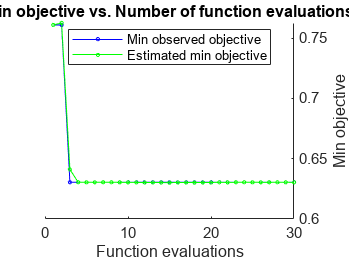


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 132.655 seconds
Total objective function evaluation time: 118.5424

Best observed feasible point:
    DistributionNames      Width         Kernel   
    _________________    _________    ____________

         kernel          0.0018107    epanechnikov

Observed objective function value = 0.63043
Estimated objective function value = 0.63045
Function evaluation time = 3.3291

Best estimated feasible point (according to models):
    DistributionNames     Width      Kernel
    _________________    ________    ______

         kernel          0.003856    normal

Estimated objective function value = 0.6304
Estimated func

Mdl_naive_bayes =   ClassificationNaiveBayes
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'Baseline'  'Before'  'After'}
                       ScoreTransform: 'none'
                      NumObservations: 46
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                    DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'}
               DistributionParameters: {3×12 cell}
                               Kernel: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
                              Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     

% Hyperparameter tune multiclass Naive Bayes
% Due to API limitiations, we specify the kfold fold number as the number of datapoints
% we collect - which is equivalent to LOOCV
% Train Naive Bayes model
Mdl_naive_bayes = fitcnb(train_data, train_label, "ClassNames", ["Baseline" "Before" "After"], "OptimizeHyperparameters","all", "HyperparameterOptimizationOptions",struct("Kfold", 46))

% Hyperparameter tune multiclass SVM
% gather hyperparameters
params = hyperparameters('fitcecoc', train_data, train_label, "svm")

params =   6×1 optimizableVariable array with properties:

    Name
    Range
    Type
    Transform
    Optimize


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.63043 |      1.1501 |     0.63043 |     0.63043 |     onevsone |      0.01113 |        317.7 |
|    2 | Best   |      0.6087 |      45.812 |      0.6087 |     0.61025 |     onevsone |     0.001653 |     0.082761 |
|    3 | Best   |     0.47826 |      55.979 |     0.47826 |     0.47828 |     onevsall |       995.14 |       77.078 |
|    4 | Accept |     0.73913 |      92.313 |     0.47826 |      0.4885 |     onevsall |       1.3251 |    0.0065421 |
|    5 | Accept |         0.5 |      46.718 |   

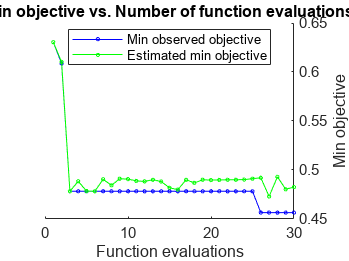


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 350.8146 seconds
Total objective function evaluation time: 337.3584

Best observed feasible point:
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsall      0.0010288        0.7199   

Observed objective function value = 0.45652
Estimated objective function value = 0.48161
Function evaluation time = 6.1261

Best estimated feasible point (according to models):
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsall      0.0010676        0.61835  

Estimated objective function value = 0.4826
Estimated function evaluatio

Mdl_svm =   ClassificationECOC
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'Baseline'  'Before'  'After'}
                       ScoreTransform: 'none'
                       BinaryLearners: {3×1 cell}
                           CodingName: 'onevsall'
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


% Provide these to the hyperparameter trainer as we only want to train on
% SVM
% Train SVM model
Mdl_svm = fitcecoc(train_data, train_label, "ClassNames", ["Baseline" "Before" "After"], "OptimizeHyperparameters",params, "HyperparameterOptimizationOptions",struct("Kfold", 46))

% Evaluate best model performance of each SVM and Naive Bayes
% best overall performance will be selected

% naive bayes loss
% Models are already cross evald, pass though this function to get correct
% type
nb_cross = crossval(Mdl_naive_bayes, test_data, test_label)

nb_cross =   ClassificationPartitionedModel
    CrossValidatedModel: 'NaiveBayes'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'}
           ResponseName: 'Y'
        NumObservations: 46
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: {'Baseline'  'Before'  'After'}
         ScoreTransform: 'none'


  Properties, Methods


nb_l = kfoldLoss(nb_cross)

nb_l = 0.6304

% svm loss
svm_Cross = crossval(Mdl_svm, test_data, test_label)

svm_Cross =   ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'}
           ResponseName: 'Y'
        NumObservations: 46
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: {'Baseline'  'Before'  'After'}
         ScoreTransform: 'none'


  Properties, Methods


svm_l = kfoldLoss(svm_Cross)

svm_l = 0.5652

% predict and confusion mat for both classifiers
preds_nb = predict(Mdl_naive_bayes, test_data)

preds_nb = 11×1 cell array
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}


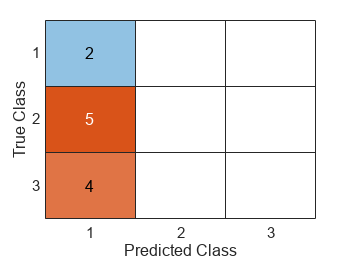

confusionchart(confusionmat(test_label, preds_nb))

preds_svm = predict(Mdl_svm, test_data)

preds_svm = 11×1 cell array
    {'Before'}
    {'After' }
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}
    {'Before'}
    {'After' }
    {'Before'}
    {'After' }


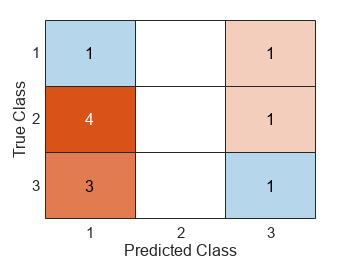

confusionchart(confusionmat(test_label, preds_svm))

% Load data from disk, segment into interseting portions, and perform
% feature computation, compose computed features into a table for 
% consumption by ML models

function feature_table = compose_data_to_feature_space()
    % Load data in form of .mat files
    % files should be present at the same directory
    % level as this script's cwd if unpacked with 
    %`fetchDataset` method defined below
    % if this is not the case, the path
    % below will require amending to the relative
    % path to the data source root
    [ecg, resp] = marshalData();  

    % setup new array to store computed features
    feature_table = zeros(height(ecg), 12);

    % compute features after validating from statistical test
    for row = 1:height(ecg)
        % get signal component of table for each component
        sigEcg = ecg(row, 3:end);
        sigResp = resp(row, 3:end);
        % perform feature computation on signal
        [avgHR,meanRR,rmssd,nn50,pNN50,sd_RR,sd_HR,pse,average_hrv,~] = getECGFeatures(table2array(sigEcg)');
        % artificially elongate resp signal as this particular matlab
        % toolbox doesn't work with signals under 30 min in length
        % since we are repeating, generally the statistics should be stable
        breath = breathmetrics(repmat(table2array(sigResp),1, 300)', 500, 'humanAirflow');
        breath.correctRespirationToBaseline('sliding', 0, 0)
        breath.estimateAllFeatures();
        [nInhalePeaks, meanPeakFlow, nInhalePauses, ~, ~] = computeBreathFeatures(breath);
        % add features from this signal into feature table
        features = [avgHR, meanRR, rmssd, nn50, pNN50, sd_RR, sd_HR, pse, average_hrv, nInhalePeaks, meanPeakFlow, nInhalePauses];
        feature_table(row, :) = features;
    end
end

% Load data into memory from disk and call `splitParticipantData` our data
% organization method
function [ecg, resp] = marshalData()
    mats = dir("*.mat");
    [ecg, resp] = splitParticipantData(mats);
end

% Decompose a single participants data into components of interest to this
% project and compose into a table representing the baseline signal data,
% and then signal bins before and after significantly anxious events
function [ecg, resp] = splitSingleParticpantData(data, particip)
    freq = 500;
    % Compute number of samples for each video
    vid0 = freq*6;
    vid1 = freq*196;
    vid2 = freq*119;
    vids = [vid1 vid2];
    % vid0 is the first few seconds of the first video
    % This video is technically anxiety inducing, but the first
    % several seconds of the video were determined to be innocuous enough
    % to be used as our baseline - future efforts could use a pretrained
    % binary anxiety classifier to prove this
    % this effort relied on the same assesment as the data collection paper
    % to determine this as finding a pretrained classifier proved quite
    % difficult in the matlab space - perhaps python may provide better
    % luck
    data_chunks = [];
    % offset is the duration of our selected clip segments - 6seconds or 3k
    % data samples 
    offset = vid0;
    baseline = data(1:offset, :);
    data_chunks = [data_chunks; baseline];
    % break dataset down into periods denoted by clips participants
    % were exposed to
    for vid = vids
        % take same number of samples from each portion of the clips
        % baseline is 3k
        data_chunks = [data_chunks; data(offset+1:offset+1+vid0,:)];
        % skip to next vid
        offset = offset+vid;
    end
    baseline_ecg = array2table(data_chunks(1:vid0, 1)');
    before_ecg = array2table(data_chunks(vid0+1:vid0*2, 1)');
    after_ecg = array2table(data_chunks((vid0*2)+3:end, 1)');
    baseline_resp = array2table(data_chunks(1:vid0, 2)');
    before_resp = array2table(data_chunks(vid0+1:vid0*2, 2)');
    after_resp = array2table(data_chunks((vid0*2)+3:end, 2)'); 
    partip = int2str(particip);
    timing = ["Baseline" "Before" "After"]';
    participant = repmat("p"+partip, 3, 1);
    ecg_table = table(participant, timing );
    resp_table = table(participant, timing);
    
    ecg_data_table = [baseline_ecg; before_ecg; after_ecg];
    ecg = [ecg_table ecg_data_table];
    resp_data_table = [baseline_resp; before_resp; after_resp];
    resp = [resp_table resp_data_table ];
end
% Take all participant signals and take components of interest to this
% project
function [ecg, resp] = splitParticipantData(mats)
    ecg = 0;
    resp = 0;

    % Data for all samples is currently spread accross multiple mat files
    % join these for easier manipulation
    for i = 1:length(mats)
        % each .mat file stores signal data for a
        % single study participant
        partip = load(mats(i).name);
        % run data preprocessing
        data = preprocess(partip.data);
        % perform data breakdown on a per participat manner
        [ecg_, resp_] = splitSingleParticpantData(data, i);
        % join data accross participants
        if ~istable(ecg)
           ecg = ecg_;
           resp = resp_;
        else
            ecg = [ecg; ecg_];
            resp = [resp; resp_];
        end
    end
end

% Fetch dataset down from web, where it is hosted as a github release
% artifact - save onto disk as "AnxietyDataSet.zip" and extract zip file
% change active working directory to the directory containing the extracted
% data files - found in .mat format
function fetchDataset(url)
    fullFilePath = websave("AnxietyDataSet.zip", url);
    unzip(fullFilePath)
    cd Data
end

%  Decompose dataset into training and testing splits
%  Decompose label data in same manner
function [test_data, test_label, train_data, train_label] = splitDataset(dataset, ground_truth)
    % select random 80% of the data to select for training
    k = randperm(57, 46);
    train_data  = dataset(k, :);
    train_label = ground_truth(k, :);
    r         = true(1,57);
    r(k)      = false;
    % We've split out the training data, now split test
    remaining_data = dataset(r, :);
    remaining_label = ground_truth(r, :);
    k = randperm(11, 11);
    test_data = remaining_data(k, :);
    test_label = remaining_label(k, :);
end

% Preprocess signal data for learning
% Perform 50/60hz notch filter pass
% Perform Chebyshev Type 2 Bandstop
function data = preprocess(data)
    % setup 50hz notch
    wo = 50/(500/2); BW = wo/35;
    [b,a] = iirnotch(wo, BW);
    % setup 60hz notch
    wo = 60/(500/2); BW = wo/35;
    [b2, a2] = iirnotch(wo, BW);
    % setup chebyshev type 2 bandstop
    [bcheb,acheb] = cheby2(3,50,[0.2 0.6],'stop');

    % filter ecg - 50hz notch, then 60hz, then Chebyshev type 2 bandstop
    [filt_ecg_50hz, ~] = filter(b,a, data(:, 1));
    [filt_ecg_50_60hz, ~] = filter(b2, a2, filt_ecg_50hz);
    [filt_ecg_cheb, ~] = filter(bcheb, acheb, filt_ecg_50_60hz);
    % Replace non denoised ecg signal with denoised signal
    % We do not filter the resp as it does not have electrical signal
    % interference and the breathmetrics toolbox used later does this for
    % us
    data(:, 1) = filt_ecg_cheb;
end
% Take in BreathMetrics toolbox object and use its API to derive features
% of interest to this project, variable names should be fairly self evident
function [nInhalePeaks, meanPeakFlow, nInhalePauses, meanBreathCatch, meanExhaleDur] = computeBreathFeatures(breath)
    nInhalePeaks = length(breath.inhalePeaks());
    meanPeakFlow = mean(breath.peakInspiratoryFlows());
    nInhalePauses = length(breath.inhaleOnsets());
    breath = findBreathAndPauseDurations(breath);
    meanBreathCatch = mean(breath.inhalePauseDurations());
    meanExhaleDur = mean(breath.exhaleDurations());
end


The section below contains code from various Matlab OS contributors on the Matlab FileExchange, each piece of code is accompanied by it's requisite docstring and author credit. Small modifications have been made on the part of this author to ensure the external code is free of bugs, mathematical errors, and is compatible with the interface desired in this project.

%% ECG feature Extractor Toolbox
% Author: Shantanu V. Deshmukh
% Organization: University of Michigan Dearborn
% Version: 1.1

% This function computes the ECG features based on temporal as well as spectral analysis
% Note: 

% avgHR=Average Heart Rate
% meanRR= mean R-R interval distance 
% rmssd= Root Mean Square Distance of Successive R-R interval
% nn50= Number of R peaks in ECG that differ more than 50 millisecond
% pnn50= percentage NN50
% sd_RR= Standard Deviation of R-R series
% sd_HR= Standard Deviation of Heart Rate
% se= Sample Entropy
% pse= Power Spectral Entropy
% average_hrv= Average Heart Rate Variability
% hrv= Heart Rate Variability

% use:[avgHR,meanRR,rmssd,nn50,pNN50,sd_RR,sd_HR,se,pse,average_hrv,hrv]= getECGFeatures(ecg_signal,winsize,wininc)
function [avgHR,meanRR,rmssd,nn50,pNN50,sd_RR,sd_HR,pse,average_hrv,hrv]= getECGFeatures(ecg_signal)

%% Removing lower frequencies
    samplingrate=500;
    fresult=fft(ecg_signal);
    fresult(1 : round(length(fresult)*5/samplingrate))=0;
    fresult(end - round(length(fresult)*5/samplingrate) : end)=0;
    corrected=real(ifft(fresult));
    
    %% Filter - first pass
    WinSize = floor(samplingrate * 571 / 1000);
    if rem(WinSize,2)==0
        WinSize = WinSize+1;
    end
    filtered1=ecgdemowinmax(corrected, WinSize);
    
    % Scale an ecg
    peaks1=filtered1/(max(filtered1)/7);
    positions=find(peaks1);
    distance=positions(2)-positions(1);
    
    % Returns minimum distance between two peaks
    for data=1:1:length(positions)-1
        if positions(data+1)-positions(data)<distance 
            distance=positions(data+1)-positions(data);
        end
    end
    
    %% Optimize filter window size
    QRdistance=floor(0.04*samplingrate);
    if rem(QRdistance,2)==0
        QRdistance=QRdistance+1;
    end
    WinSize=2*distance-QRdistance;
    
    %% Filter - second pass
    filtered2=ecgdemowinmax(corrected, WinSize);
    peaks2=filtered2;
    
%% Plotting the HRV Heart Rate Variability
    [pks,locs]=find(peaks2);

     % Number of R-peaks 
     num_R_peaks=length(pks);
     % Calculating Average Heart Rate
     time_in_sec=(WinSize/samplingrate);
     averageHeartRate=(num_R_peaks/time_in_sec)*60;
     avgHR=averageHeartRate;
     
     positions2=find(peaks2);
    for count=1:1:length(positions2)-1
        dstnce(count)=positions2(count+1)-positions2(count); % average the dstance to get average hrv in order to have one measure per window
        heartRate(count)=60*samplingrate/dstnce(count);
    end
    
    %Average HRV Calculation
    average_hrv=mean(dstnce);
    
%% HRV Parameters
% note RRinterval=dstnce array 
    %extracting Mean R-R interval
    mean_rr_interval=sum(dstnce)/length(dstnce);
    
    %Extracting Root Mean Square of the differences of successive R-R
    %interval    
    square_dstnce=dstnce.^2;
    avg_square_dstnce=sum(square_dstnce)/length(square_dstnce);
    rmssd_this=sqrt(avg_square_dstnce);
       
    %Extracting number of consecutive R-R intervals that differ more than
    %50 ms
    m=0;
    for num=1:1:length(dstnce)-1
        if(dstnce(num+1)-dstnce(num)<50)
            m=m+1;
        end
    end
    
    %Extracting Percentage value of total consecutive RR interval that
    %differ more than 50ms
    percentage_nn50= ((m/length(dstnce))*100);
    
    %Extracting Standard Deviation of RR interval series
    for num1=1:1:length(dstnce)
        sd1=mean_rr_interval-dstnce(num1);
    end
    sd2=sd1.^2;
    sd3=sum(sd2)/length(sd2);
    sd_final=sqrt(sd3);
    
    %Extracting Standard Dviation of Heart Rate
    for num2=1:1:length(heartRate)
        sd_heart1=averageHeartRate-heartRate(num2);
    end
    sd_heart2=sd_heart1.^2;
    sd_heart3=sum(sd_heart2)/length(sd_heart2);
    sd_heart_final=sqrt(sd_heart3);
    
%% Calculating Sample Entropy
    
%    sampleEntropy(counter) = SampEn( 2, 0.2, filtered2, 1 );
    
%% Calculating Power Spectral density 

    % Calculating Power Spectral Entropy
    Fs1=250; %sampling rate per second
    Ts1=1/Fs1;%sampling time interval in second
    t1=0:Ts1:1-Ts1; n1=length(t1);

    fresult1=fft(dstnce);
    sum_fresult1=0.0;
    for i=1:1:length(fresult1)-1
     sum_fresult1= sum_fresult1 + (abs(fresult1(i)));
    end
    fresult1=fresult1/sum_fresult1;
    entropy1=0.0;
    for i=1:1:length(fresult1)-1
     entropy1= entropy1+ abs(fresult1(i))*log(1/abs(fresult1(i)));
     pse_rr=entropy1;
    end
    
    hrv=dstnce;
    meanRR=mean_rr_interval;
    rmssd=rmssd_this;
    nn50=m;
    pNN50=percentage_nn50;
    sd_RR= sd_final;  
    sd_HR=sd_heart_final;      
    %se=sampleEntropy;
    pse=pse_rr;

end

%   ECGDEMO    ECG PROCESSING DEMONSTRATION - R-PEAKS DETECTION
%              
%              This file is a part of a package that contains 5 files:
%
%                     1. ecgdemo.m - main script file;
%                     2. ecgdemowinmax.m - (this file) window filter script file;
%                     3. ecgdemodata1.mat - first ecg data sample;
%                     4. ecgdemodata2.mat - second ecg data sample;
%                     5. readme.txt - description.
%
%              The package downloaded from http://www.librow.com
%              To contact the author of the sample write to Sergey Chernenko:
%              S.Chernenko@librow.com
%
%              To run the demo put
%
%                     ecgdemo.m;
%                     ecgdemowinmax.m;
%                     ecgdemodata1.mat;
%                     ecgdemodata2.mat;
%
%              in MatLab's "work" directory, run MatLab and type in
%
%                     >> ecgdemo
%
%              The code is property of LIBROW
%              You can use it on your own
%              When utilizing credit LIBROW site

function Filtered=ecgdemowinmax(Original, WinSize)

   
    %initialising variables
    WinHalfSize = floor(WinSize/2);
    WinHalfSizePlus = WinHalfSize+1;
    WinSizeSpec = WinSize-1;
    FrontIterator = 1;
    WinPos = WinHalfSize;
    WinMaxPos = WinHalfSize;
    WinMax = Original(1);
    OutputIterator = 0;
    Filtered=[];
    
    try
    
    % Finding the postion of the largest value in window
    for LengthCounter = 0:1:WinHalfSize-1 
        if Original(FrontIterator+1) > WinMax
            WinMax = Original(FrontIterator+1);
            WinMaxPos = WinHalfSizePlus + LengthCounter;
        end
        FrontIterator=FrontIterator+1;
    end
    % if the first point is the highest, set ouput 1
    if WinMaxPos == WinHalfSize 
        Filtered(OutputIterator+1)=WinMax;
    else
        Filtered(OutputIterator+1)=0;
    end
    OutputIterator = OutputIterator+1;
    
    % search next half of signal
    for LengthCounter = 0:1:WinHalfSize-1 
        if Original(FrontIterator+1)>WinMax
            WinMax=Original(FrontIterator+1);
            WinMaxPos=WinSizeSpec;
        else
            WinMaxPos=WinMaxPos-1;
        end
        if WinMaxPos == WinHalfSize
            Filtered(OutputIterator+1)=WinMax;
        else
            Filtered(OutputIterator+1)=0;
        end
        FrontIterator = FrontIterator+1;
        OutputIterator = OutputIterator+1;
    end
    for FrontIterator=FrontIterator:1:length(Original)-1
        if Original(FrontIterator+1)>WinMax
            WinMax=Original(FrontIterator+1);
            WinMaxPos=WinSizeSpec;
        else
            WinMaxPos=WinMaxPos-1;
            if WinMaxPos < 0
                WinIterator = FrontIterator-WinSizeSpec;
                WinMax = Original(WinIterator+1);
                WinMaxPos = 0;
                WinPos=0;
                for WinIterator = WinIterator:1:FrontIterator
                    if Original(WinIterator+1)>WinMax
                        WinMax = Original(WinIterator+1);
                        WinMaxPos = WinPos;
                    end
                    WinPos=WinPos+1;
                end
            end
        end
        if WinMaxPos==WinHalfSize
            Filtered(OutputIterator+1)=WinMax;
        else
            Filtered(OutputIterator+1)=0;
        end
        OutputIterator=OutputIterator+1;
    end
    WinIterator = WinIterator-1;
    WinMaxPos = WinMaxPos-1;
    for LengthCounter=1:1:WinHalfSizePlus-1
        if WinMaxPos<0
            WinIterator=length(Original)-WinSize+LengthCounter;
            WinMax=Original(WinIterator+1);
            WinMaxPos=0;
            WinPos=1;
            for WinIterator=WinIterator+1:1:length(Original)-1
                if Original(WinIterator+1)>WinMax
                    WinMax=Original(WinIterator+1);
                    WinMaxPos=WinPos;
                end
                WinPos=WinPos+1;
            end
        end
        if WinMaxPos==WinHalfSize
            Filtered(OutputIterator+1)=WinMax;
        else
            Filtered(OutputIterator+1)=0;
        end
        FrontIterator=FrontIterator-1;
        WinMaxPos=WinMaxPos-1;
        OutputIterator=OutputIterator+1;
    end
    catch
    end
end

function saen = SampEn( dim, r, data, tau )
% SAMPEN Sample Entropy
%   calculates the sample entropy of a given time series data
%   SampEn is conceptually similar to approximate entropy (ApEn), but has
%   following differences:
%       1) SampEn does not count self-matching. The possible trouble of
%       having log(0) is avoided by taking logarithm at the latest step.
%       2) SampEn does not depend on the datasize as much as ApEn does. The
%       comparison is shown in the graph that is uploaded.
%   dim     : embedded dimension
%   r       : tolerance (typically 0.2 * std)
%   data    : time-series data
%   tau     : delay time for downsampling (user can omit this, in which case
%             the default value is 1)
%
%---------------------------------------------------------------------
% coded by Kijoon Lee,  kjlee@ntu.edu.sg
% Mar 21, 2012
%---------------------------------------------------------------------
if nargin < 4, tau = 1; end
if tau > 1, data = downsample(data, tau); end
N = length(data);
correl = zeros(1,2);
dataMat = zeros(dim+1,N-dim);
for i = 1:dim+1
    dataMat(i,:) = data(i:N-dim+i-1);
end
for m = dim:dim+1
    count = zeros(1,N-dim);
    tempMat = dataMat(1:m,:);
    
    for i = 1:N-m
        % calculate Chebyshev distance, excluding self-matching case
        dist = max(abs(tempMat(:,i+1:N-dim) - repmat(tempMat(:,i),1,N-dim-i)));
        
        % calculate Heaviside function of the distance
        % User can change it to any other function
        % for modified sample entropy (mSampEn) calculation
        D = (dist < r);
        
        count(i) = sum(D)/(N-dim);
    end
    
    correl(m-dim+1) = sum(count)/(N-dim);
end
saen = log(correl(1)/correl(2));
end